Controladores no EE

clear all

%constantes

m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

%coeficientes de arrasto hidrodinamico

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

%velocidades iniciais

U = 0.5;
V = 0.5;
R = 0.126;

Matrizes

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v);
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];

B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C = [1,0,0];

D = zeros(1,3);

E = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

B_novo = [B E];

D_novo = zeros(1,6);




Descretização e condições iniciais

t_ = 0:0.1:60;

x0 = [0;0;0];

w1 = zeros(size(t_));

for i = 1:1:601
   w1(i) = 5*sin(2*pi()*0.1*t_(i));
end

w2 = zeros(size(t_));

for i = 1:1:50
    w2(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 51:1:56
    w2(i) = 5*sin(2*pi()*0.1*t_(i)) + 2000; %tubarão branco 1(m/s) 0.5s de impacto 1000kg
end
for i = 57:1:350
    w2(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 351:1:356
    w2(i) = 5*sin(2*pi()*0.1*t_(i)) - 400; %tubarão-tigre 1(m/s) 0.5s de impacto 200kg
end
for i = 357:1:601
    w2(i) = 5*sin(2*pi()*0.1*t_(i));
end

z_ = zeros(size(t_));

w22 = zeros(size(t_));

for i = 1:1:50
    w22(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 51:1:56
    w22(i) = 5*sin(2*pi()*0.1*t_(i)) - 2000; %tubarão branco 1(m/s) 0.5s de impacto 1000kg
end
for i = 57:1:350
    w22(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 351:1:356
    w22(i) = 5*sin(2*pi()*0.1*t_(i)) + 400; %tubarão-tigre 1(m/s) 0.5s de impacto 200kg
end
for i = 357:1:601
    w22(i) = 5*sin(2*pi()*0.1*t_(i));
end
u_22 = [w22;w1;z_];


u_ = [w2;w1;z_];

Por alocação de polos

polos = [-2.5+ 0.3 * j, -2.5 - 0.3 * j, -1.5];

Kaloc = place(A,B,polos)

Kaloc =   735.1750  205.6849  279.4600
 -224.4856  883.3500 -225.4350
  -54.0250  -54.0250  317.0806



Faloc = A-B*Kaloc; 

sysaloc = ss(Faloc,B,C,D);

[h3_, t2, xal] = lsim(sysaloc, u_, t_, x0);
[h3_1, t21, xal1] = lsim(sysaloc, u_22, t_, x0);
q1aloc = U + h3_;

q1_ = transpose(q1aloc);

Por malha aberta

sl = ss(A, B, C, D);

[y,x] = lsim(sl, u_, t_, x0);
y = transpose(y);

q1=  transpose(U + y(1,:)); 

Por LQR

Q = diag([11000,10000,3500]);
R_ = diag([0.01,0.02,0.05]);

K = lqr(A,B,Q,R_)

K =   717.4089   15.9483   81.6220
    6.4326  364.7101  -71.3020
   30.7392  -66.5755  258.5663



F = A-B*K; 

sysF = ss(F,B,C,D); 


[h1_,t1,xlq] = lsim(sysF, u_, t_, x0); 
[h1_1,t11,xlq1] = lsim(sysF, u_22, t_, x0);

q1_lqr=  transpose(U + h1_(:,1)); 

força feita pelo atuador

ulq_x = xlq1(:,1) + U;
ulq_y = xlq1(:,2) + V;
ulq_r = xlq1(:,3) + R;
ual_x = xal1(:,1) + U;
ual_y = xal1(:,2) + V;
ual_r = xal1(:,3) + R;

ulq = [ulq_x, ulq_y, ulq_r];
ual = [ual_x, ual_y, ual_r];

ulq = K*(ulq)';
ual = Kaloc*(ual)';


Plots dos resultados

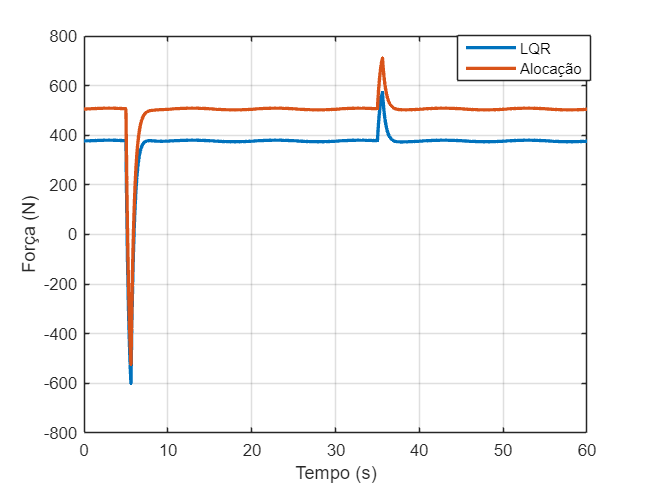

figure (1)
plot(t_, ulq(1,:),t_, ual(1,:), 'LineWidth', 2)
grid on 
legend('LQR', 'Alocação')
% title('Força de atuação em x')
xlabel('Tempo (s)')
ylabel('Força (N)')

legend("Position", [0.71189,0.83714,0.19187,0.087298])

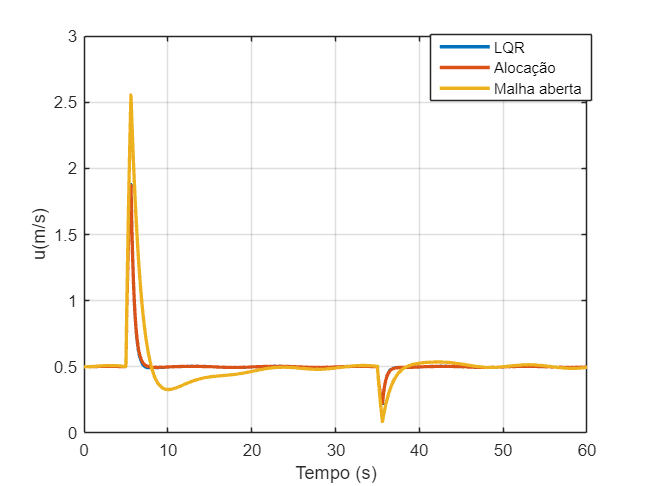




figure (2)
plot(t_, q1_lqr, t_, q1_, t_, q1, 'LineWidth', 2)
grid on
legend('LQR', 'Alocação', 'Malha aberta')
% title('Velocidade u')
xlabel('Tempo (s)')
ylabel('u(m/s)')
% ylim([0.46 0.54])

legend("Position", [0.672,0.79792,0.23176,0.12652])
hold off

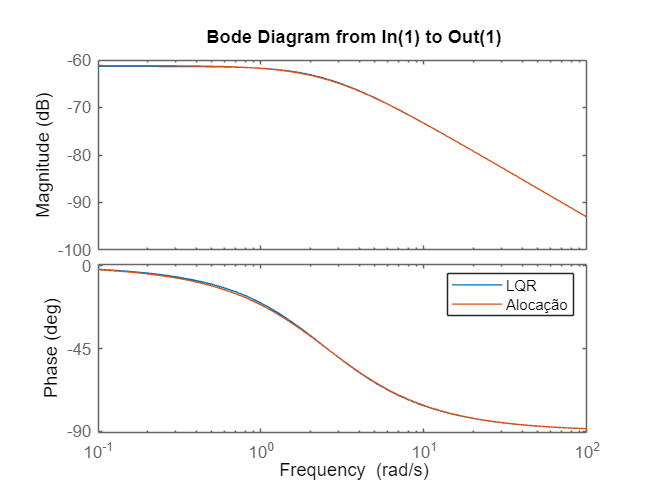

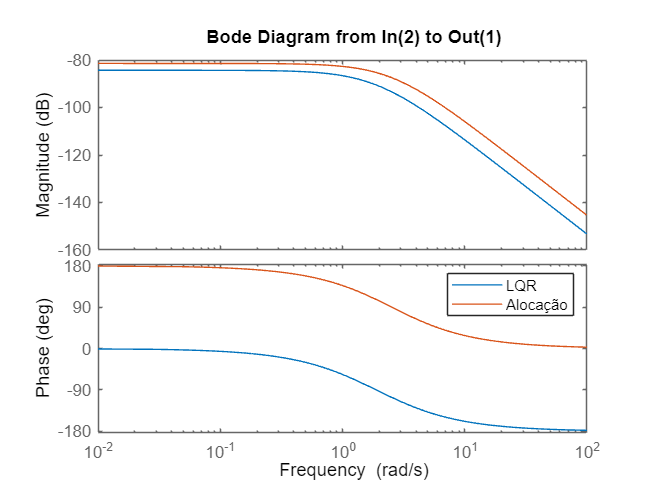

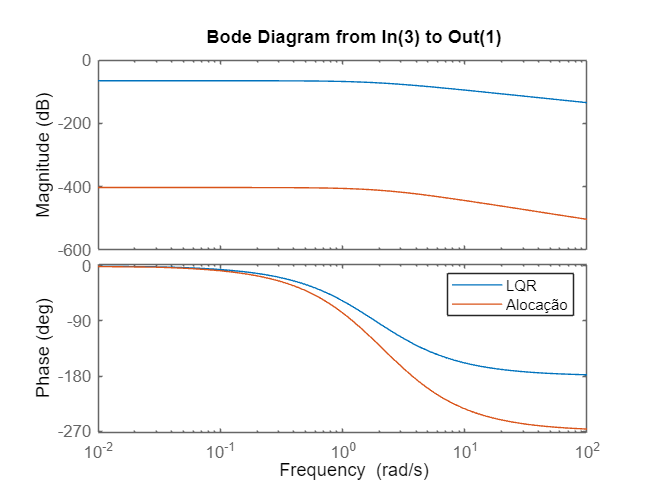



[num_outputs, num_inputs] = size(D);

for i = 1:num_inputs
    for j = 1:num_outputs
        % Extrair o sub-sistema para a entrada i e saída j
        sys_ij = ss(F, B(:, i), C(j, :), D(j, i));
        sys_ij2 = ss(Faloc,B(:, i), C(j, :), D(j, i));
        % Plotar o diagrama de Bode para o sub-sistema
        figure;
        bode(sys_ij);
        hold on
        bode(sys_ij2);
        title(sprintf('Bode Diagram from In(%d) to Out(%d)', i, j));
        legend('LQR','Alocação');
    end
end